syms A C
assume(A>0)
ff=C*(1-C)/(C+(1-C)*A)

$$ff = -\frac{C\,\left(C-1\right)}{C-A\,\left(C-1\right)}$$

df=simplify(diff(ff,C))

$$df = \frac{A+A\,C^{2}-C^{2}-2\,A\,C}{{\left(A+C-A\,C\right)}^{2}}$$

simplify(solve(df==0,C))

$$ans = \left(\begin{array}{c} \frac{A+\sqrt{A}}{A-1}\\ \frac{\sqrt{A}}{\sqrt{A}+1} \end{array}\right)$$

F=@(N,N0,w) N0*(N-N0)./(N0+(N-N0)*exp(-w)).*w.^2.* ...
    (exp(2*w)./(1+exp(w)).^3 + (exp(-3*w)./(1+exp(-w)).^3));

## the analytic solution by assuming N0=CN

A=@(w) exp(w);
C=@(w) sqrt(A(-w))./(1+sqrt(A(-w)));
%g=@(w) w.^2.*C(w).*(1-C(w))./(C(w)+(1-C(w)).*A(-w)) .* ...
    (A(2*w)./(1+A(w)).^3 + A(-3*w)./(1+A(-w)).^3);

%f=@(w) w.^2.*(1-(2*exp(-2*w)+2*exp(-w))./sqrt(exp(-2*w)+exp(-w)) + 2*exp(-w))...
 %   .* (exp(2*w)./(1+exp(w)).^3 + (exp(-3*w)./(1+exp(-w)).^3))
f=@(w) w.^2.*C(w).*(1-C(w))./(C(w)+(1-C(w)).*exp(-w)) ...
    .* (exp(2*w)./(1+exp(w)).^3 + exp(-3*w)./(1+exp(-w)).^3)

f = function_handle with value:
    @(w)w.^2.*C(w).*(1-C(w))./(C(w)+(1-C(w)).*exp(-w)).*(exp(2*w)./(1+exp(w)).^3+exp(-3*w)./(1+exp(-w)).^3)


ww=0:1e-7:7;
wopt=ww(f(ww)==max(f(ww)))

wopt = 2.9682

fopt=f(wopt)

fopt = 0.2596

copt=C(wopt)

copt = 0.1848

n=10;
Fopt=F(2^n,max(floor(2^n*copt),1),wopt)/2^n

Fopt = 0.2596

%figure
%plot(ww,[f(ww);g(ww)])

## The width of optimal thermometer

Does the optimal thermometer has a width that shrinks with n? (like equilibrium thermometers)

nmin=2;nmax=10;
T0=1;%Saym this is what I think is the correct temperature
w0=wopt*T0;%This is what I think is the best gap.
figure
hold on
TT=0.01:0.01:10;
for in=[1,10,100]
    N=2^in;
    N0=max(1,floor(copt*N))
    loglog(TT./T0,F(N,N0,w0./TT))
end
%%% Normalised figure
figure
hold on
TT=0.01:0.01:10;
for in=[1,10,100]
    N=2^in;
    N0=max(1,floor(copt*N))
    loglog(TT./T0,F(N,N0,w0./TT)./max(F(N,N0,w0./TT)))
end

## The empirical FI (F^emp)

%%%This is just a check, the actual expression is in the section below
syms w T x N N0 gamma
N=2^3;
for N00=1:N
N0=N00;
evec=[zeros(1,N0), w*ones(1,N-N0)];
sw=length(evec);
pvec=exp(-evec/T);
pvec=pvec/sum(pvec);
P=diag(pvec);
dP=diff(pvec,T);
nmat=sym(zeros(sw,sw));
for iw=1:sw
    for jw=1:sw
        wij=evec(1,iw)-evec(1,jw);
        nmat(iw,jw)=1./(1+exp(wij/T));
    end
end
Gamma=gamma*transpose(nmat);
Gamma=Gamma-diag(sum(Gamma,1));
simplify(Gamma);
simplify(P\Gamma);
%%%
F_emp=-1/2*dP/P*Gamma*transpose(dP);
simplify(F_emp);
%%%
F_emp=0;
for iw=1:sw
    for jw=1:sw
        dummy=dP(1,iw)*Gamma(iw,jw)/pvec(1,iw)*dP(1,jw);
        F_emp=F_emp+dummy;
    end
end
F_emp=-1/2*F_emp;
simplify(F_emp)
end

$$dP = \begin{array}{l} \left(\begin{array}{cccccccc} -\frac{7\,w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,{\left(7\,{\mathrm{e}}^{-\frac{w}{T}}+1\right)}^{2}} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,\left(7\,{\mathrm{e}}^{-\frac{w}{T}}+1\right)}-\frac{7\,w\,{\mathrm{e}}^{-\frac{2\,w}{T}}}{T^{2}\,{\left(7\,{\mathrm{e}}^{-\frac{w}{T}}+1\right)}^{2}} \end{array}$$

$$ans = \frac{7\,\gamma \,w^{2}\,{\mathrm{e}}^{w/T}\,\left(7\,{\mathrm{e}}^{w/T}+1\right)}{2\,T^{4}\,\left({\mathrm{e}}^{w/T}+1\right)\,{\left({\mathrm{e}}^{w/T}+7\right)}^{2}}$$

$$dP = \begin{array}{l} \left(\begin{array}{cccccccc} -\frac{6\,w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,{\left(6\,{\mathrm{e}}^{-\frac{w}{T}}+2\right)}^{2}} & -\frac{6\,w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,{\left(6\,{\mathrm{e}}^{-\frac{w}{T}}+2\right)}^{2}} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,\left(6\,{\mathrm{e}}^{-\frac{w}{T}}+2\right)}-\frac{6\,w\,{\mathrm{e}}^{-\frac{2\,w}{T}}}{T^{2}\,{\left(6\,{\mathrm{e}}^{-\frac{w}{T}}+2\right)}^{2}} \end{array}$$

$$ans = \frac{3\,\gamma \,w^{2}\,{\mathrm{e}}^{w/T}\,\left(3\,{\mathrm{e}}^{w/T}+1\right)}{T^{4}\,\left({\mathrm{e}}^{w/T}+1\right)\,{\left({\mathrm{e}}^{w/T}+3\right)}^{2}}$$

$$dP = \begin{array}{l} \left(\begin{array}{cccccccc} \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,\left(5\,{\mathrm{e}}^{-\frac{w}{T}}+3\right)}-\frac{5\,w\,{\mathrm{e}}^{-\frac{2\,w}{T}}}{T^{2}\,{\left(5\,{\mathrm{e}}^{-\frac{w}{T}}+3\right)}^{2}}\\ \sigma_{2}=-\frac{5\,w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,{\left(5\,{\mathrm{e}}^{-\frac{w}{T}}+3\right)}^{2}} \end{array}$$

$$ans = \frac{15\,\gamma \,w^{2}\,{\mathrm{e}}^{w/T}\,\left(5\,{\mathrm{e}}^{w/T}+3\right)}{2\,T^{4}\,\left({\mathrm{e}}^{w/T}+1\right)\,{\left(3\,{\mathrm{e}}^{w/T}+5\right)}^{2}}$$

$$dP = \begin{array}{l} \left(\begin{array}{cccccccc} \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,\left(4\,{\mathrm{e}}^{-\frac{w}{T}}+4\right)}-\frac{4\,w\,{\mathrm{e}}^{-\frac{2\,w}{T}}}{T^{2}\,{\left(4\,{\mathrm{e}}^{-\frac{w}{T}}+4\right)}^{2}}\\ \sigma_{2}=-\frac{4\,w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,{\left(4\,{\mathrm{e}}^{-\frac{w}{T}}+4\right)}^{2}} \end{array}$$

$$ans = \frac{2\,\gamma \,w^{2}\,{\mathrm{e}}^{w/T}}{T^{4}\,{\left({\mathrm{e}}^{w/T}+1\right)}^{2}}$$

$$dP = \begin{array}{l} \left(\begin{array}{cccccccc} \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{1} & \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,\left(3\,{\mathrm{e}}^{-\frac{w}{T}}+5\right)}-\frac{3\,w\,{\mathrm{e}}^{-\frac{2\,w}{T}}}{T^{2}\,{\left(3\,{\mathrm{e}}^{-\frac{w}{T}}+5\right)}^{2}}\\ \sigma_{2}=-\frac{3\,w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,{\left(3\,{\mathrm{e}}^{-\frac{w}{T}}+5\right)}^{2}} \end{array}$$

$$ans = \frac{15\,\gamma \,w^{2}\,{\mathrm{e}}^{w/T}\,\left(3\,{\mathrm{e}}^{w/T}+5\right)}{2\,T^{4}\,\left({\mathrm{e}}^{w/T}+1\right)\,{\left(5\,{\mathrm{e}}^{w/T}+3\right)}^{2}}$$

$$dP = \begin{array}{l} \left(\begin{array}{cccccccc} \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{2} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{2\,w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,{\left(2\,{\mathrm{e}}^{-\frac{w}{T}}+6\right)}^{2}}\\ \sigma_{2}=\frac{w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,\left(2\,{\mathrm{e}}^{-\frac{w}{T}}+6\right)}-\frac{2\,w\,{\mathrm{e}}^{-\frac{2\,w}{T}}}{T^{2}\,{\left(2\,{\mathrm{e}}^{-\frac{w}{T}}+6\right)}^{2}} \end{array}$$

$$ans = \frac{3\,\gamma \,w^{2}\,{\mathrm{e}}^{w/T}\,\left({\mathrm{e}}^{w/T}+3\right)}{T^{4}\,\left({\mathrm{e}}^{w/T}+1\right)\,{\left(3\,{\mathrm{e}}^{w/T}+1\right)}^{2}}$$

$$dP = \begin{array}{l} \left(\begin{array}{cccccccc} \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1} & \frac{w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,\left({\mathrm{e}}^{-\frac{w}{T}}+7\right)}-\frac{w\,{\mathrm{e}}^{-\frac{2\,w}{T}}}{T^{2}\,{\left({\mathrm{e}}^{-\frac{w}{T}}+7\right)}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{w\,{\mathrm{e}}^{-\frac{w}{T}}}{T^{2}\,{\left({\mathrm{e}}^{-\frac{w}{T}}+7\right)}^{2}} \end{array}$$

$$ans = \frac{7\,\gamma \,w^{2}\,{\mathrm{e}}^{w/T}\,\left({\mathrm{e}}^{w/T}+7\right)}{2\,T^{4}\,\left({\mathrm{e}}^{w/T}+1\right)\,{\left(7\,{\mathrm{e}}^{w/T}+1\right)}^{2}}$$

$$dP = \left(\begin{array}{cccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$ans = 0$$

syms w T N0 N
nF=1/(1+exp(w/T))

$$nF = \frac{1}{{\mathrm{e}}^{w/T}+1}$$

p0=1./(N0+(N-N0)*exp(-w/T))

$$p0 = \frac{1}{N_{0}+{\mathrm{e}}^{-\frac{w}{T}}\,\left(N-N_{0}\right)}$$

p1=exp(-w/T)./(N0+(N-N0)*exp(-w/T));
dp0=diff(p0,T)

$$dp0 = -\frac{w\,{\mathrm{e}}^{-\frac{w}{T}}\,\left(N-N_{0}\right)}{T^{2}\,{\left(N_{0}+{\mathrm{e}}^{-\frac{w}{T}}\,\left(N-N_{0}\right)\right)}^{2}}$$

dp1=-N0/(N-N0)*dp0;
wi0j0=1/2;%both belonging to the GS manifold, but not equal
wi1j1=1/2;%both belonging to the ES manifold, but not equal
wi1j0=nF;%first from the GS, the other from the ES
wi0j1=subs(nF,w,-w);%first from the ES, the other from the GS
simplify(wi0j1/wi1j0)%detailed balance

$$ans = {\mathrm{e}}^{w/T}$$

w00=-(N0-1)/2 - (N-N0)*wi1j0;%equal, from the GS
w11=-(N-N0-1)/2 - N0*wi0j1;%equal from the ES
F_emp=N0*dp0*dp0/p0*(w00+(N0-1)*wi0j0);
F_emp=F_emp+(N-N0)*dp1*dp1/p1*(w11+(N-N0-1)*wi1j1);
F_emp=F_emp+N0*(N-N0)*dp0*dp1/p0*wi0j1;
F_emp=F_emp+N0*(N-N0)*dp0*dp1/p1*wi1j0;
Femp1=subs(simplify(-F_emp/2),[T,w],[1,x])

$$Femp1 = \frac{N_{0}\,x^{2}\,{\mathrm{e}}^{x}\,\left(N-N_{0}\right)}{2\,\left({\mathrm{e}}^{x}+1\right)\,\left(N-N_{0}+N_{0}\,{\mathrm{e}}^{x}\right)}$$

Femp=matlabFunction(Femp1)

Femp = function_handle with value:
    @(N,N0,x)(N0.*x.^2.*exp(x).*(N-N0))./((exp(x)+1.0).*(N-N0+N0.*exp(x)).*2.0)


%%%Aand here we optimise it
syms C A
assume(A>0)
empFF=C*(1-C)./(1+C*(A-1))

$$empFF = -\frac{C\,\left(C-1\right)}{C\,\left(A-1\right)+1}$$

dempFF=diff(empFF,C)

$$dempFF = \frac{C\,\left(A-1\right)\,\left(C-1\right)}{{\left(C\,\left(A-1\right)+1\right)}^{2}}-\frac{C}{C\,\left(A-1\right)+1}-\frac{C-1}{C\,\left(A-1\right)+1}$$

S=solve(dempFF,C)

$$S = \left(\begin{array}{c} \frac{1}{\sqrt{A}+1}\\ -\frac{1}{\sqrt{A}-1} \end{array}\right)$$

%%%
A=@(w) exp(w);
C=@(w) sqrt(A(-w))./(1+sqrt(A(-w)));
fprime=@(x) C(x).*(1-C(x))./(C(x)+(1-C(x)).*A(-x)) ...
    .* x.^2./(2*(A(x)+1));
ww=0:1e-7:7;
wopt=ww(fprime(ww)==max(fprime(ww)))

wopt = 2.7233

fprimeopt=fprime(wopt)

fprimeopt = 0.1448

copt=C(wopt)

copt = 0.2040

## Fermionic Reset and Repeat Max

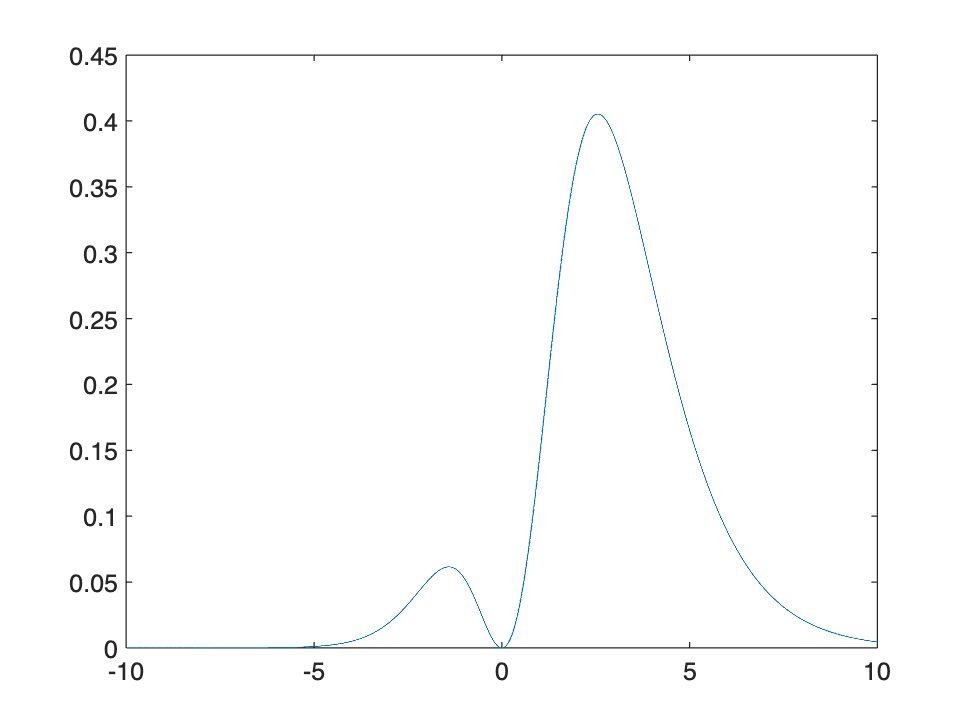

f=@(x) x.^2.*(exp(2*x)./(1+exp(x)).^3);
xx=-10:0.001:10;
figure
plot(xx,f(xx))

max(f(xx))

ans = 0.4052

xx(f(xx)==max(f(xx)))

ans = 2.5530